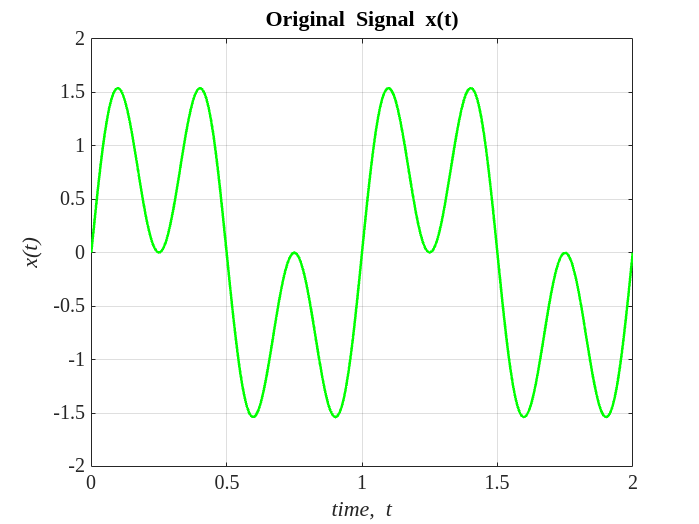

clc; clear; close all;
A1 = 1; 
A3 = 1;
f1 = 1;
f3 = 3*f1; 
K2 = 8;
K1 = 5; 
fS = K1 * K2 * f3;  


Tmax = 2;  
Ts = 1/fS; 
t = 0:Ts:Tmax; 
n_samples = length(t);

x = A1 * cos(2 * pi * f1 * t - pi/2) + A3 * cos(2 * pi * f3 * t - pi/2);

xQ = zeros(1, n_samples); 
eQ = zeros(1, n_samples); 
Delta = 0.2; 

for n = 2:n_samples
    e = x(n) - xQ(n-1);   
    eQ(n) = Delta * sign(e); 
    xQ(n) = xQ(n-1) + eQ(n); 
end

figure;
plot(t, x, 'g', 'LineWidth', 1.5);
xlabel('\it{time, t}', 'FontSize', 14);
ylabel('\it{x(t)}', 'FontSize', 14);
title('\bf{Original Signal x(t)}', 'FontSize', 16);
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

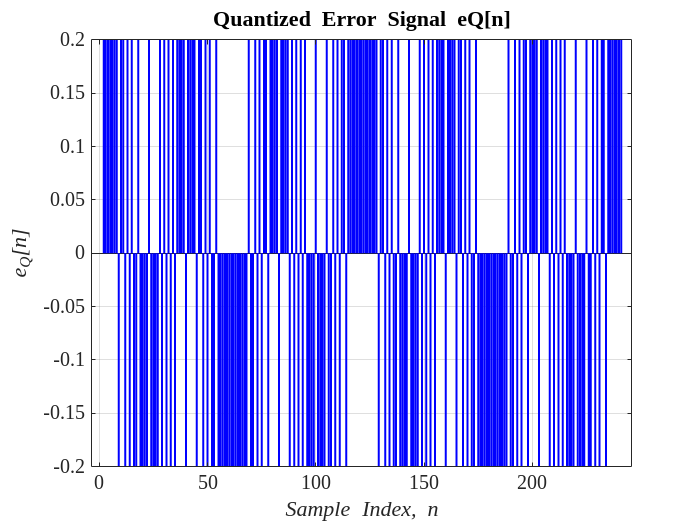


figure;
stem(1:n_samples, eQ, 'b', 'Marker', 'none', 'LineWidth', 1.2);
xlabel('\it{Sample Index, n}', 'FontSize', 14);
ylabel('\it{e_Q[n]}', 'FontSize', 14);
title('\bf{Quantized Error Signal eQ[n]}', 'FontSize', 16);
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

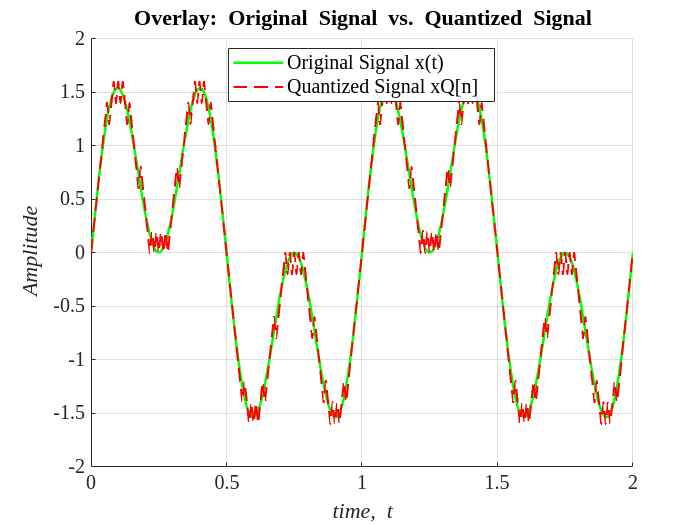


figure;
hold on;
plot(t, x, 'g', 'LineWidth', 1.5);
plot(t, xQ, 'r--', 'LineWidth', 1.2); 
hold off;
xlabel('\it{time, t}', 'FontSize', 14);
ylabel('\it{Amplitude}', 'FontSize', 14);
title('\bf{Overlay: Original Signal vs. Quantized Signal}', 'FontSize', 16);
legend({'Original Signal x(t)', 'Quantized Signal xQ[n]'}, 'FontSize', 12, 'Location', 'best');
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

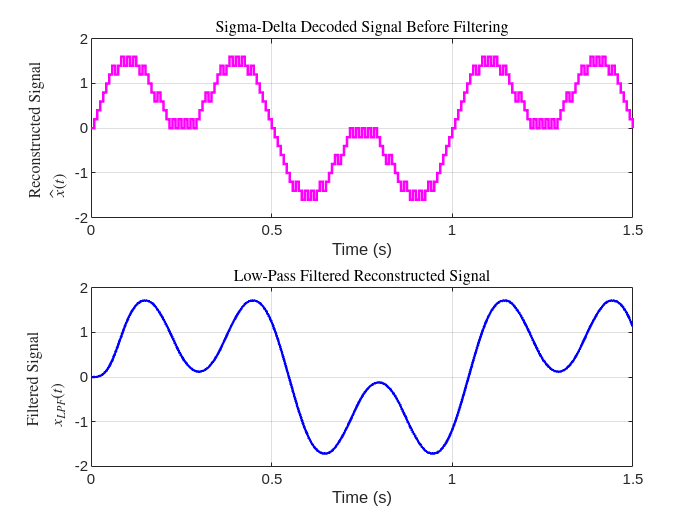

%activity 2:
clc; clear; close all;

A1 = 1; 
A3 = 1;
f1 = 1;
f3 = 3 * f1;  
K2 = 8;
K1 = 5;  
fS = K1 * K2 * f3;  

Tmax = 1.5; 
Ts = 1 / fS; 
t = 0:Ts:Tmax; 
n_samples = length(t); 
x = A1 * cos(2 * pi * f1 * t - pi/2) + A3 * cos(2 * pi * f3 * t - pi/2);

xQ = zeros(1, n_samples); 
eQ = zeros(1, n_samples); 
Delta = 0.2;

for n = 2:n_samples
    e = x(n) - xQ(n-1);   
    eQ(n) = Delta * sign(e); 
    xQ(n) = xQ(n-1) + eQ(n); 
end

x_hat = cumsum(eQ); 
M = 5;  
x_hat_padded = zeros(1, M * length(x_hat)); 
x_hat_padded(1:M:end) = x_hat; 
t_padded = linspace(0, Tmax, length(x_hat_padded)); 

p = 6; 
dt = Ts / M;
h = sinc([-p*M:p*M] * fS * dt / p) / p; 

x_LPF = filter(h, 1, x_hat_padded);

figure;

subplot(2,1,1);
stairs(t, x_hat, 'm', 'LineWidth', 1.5); 
xlabel('Time (s)'); 
ylabel('Reconstructed Signal $$\hat{x}(t)$$', 'Interpreter', 'latex');
title('Sigma-Delta Decoded Signal Before Filtering', 'Interpreter', 'latex');
grid on;
xlim([0 Tmax]); ylim([-2 2]);

subplot(2,1,2);
plot(t_padded, x_LPF, 'b', 'LineWidth', 1.5);
xlabel('Time (s)'); 
ylabel('Filtered Signal $$x_{LPF}(t)$$', 'Interpreter', 'latex');
title('Low-Pass Filtered Reconstructed Signal', 'Interpreter', 'latex');
grid on;
xlim([0 Tmax]); ylim([-2 2]); 

clc; clear; close all;

[audio_in, Fs] = audioread('lab5.mp3');  
audio_in = mean(audio_in, 2); 
audio_in = audio_in / max(abs(audio_in));  
filter_order = 6;
[b, a] = butter(filter_order, 0.9, 'low');  
audio_filtered = filtfilt(b, a, audio_in);  

Fs_new = 4 * Fs; 

t_original = (0:length(audio_filtered)-1) / Fs;  
t_resampled = (0:length(audio_filtered)*Fs_new/Fs-1) / Fs_new;  
audio_resampled = interp1(t_original, audio_filtered, t_resampled, 'spline');  

delta = 0.05; 
xQ = zeros(size(audio_resampled));
eQ = zeros(size(audio_resampled)); 

for n = 2:length(audio_resampled)
    e_n = audio_resampled(n) - xQ(n-1);  
    eQ(n) = delta * sign(e_n); 
    xQ(n) = xQ(n-1) + eQ(n);  
end

x_hat = cumsum(eQ); 

[b_lpf, a_lpf] = butter(6, 0.1, 'low');  
x_LPF = filtfilt(b_lpf, a_lpf, x_hat);
x_LPF = x_LPF / max(abs(x_LPF)); 
t_new = (0:length(x_LPF)-1) / Fs_new; 
t_original = (0:length(x_LPF)*Fs/Fs_new-1) / Fs; 
x_reconstructed = interp1(t_new, x_LPF, t_original, 'spline');  

[correlation, lags] = xcorr(audio_in, x_reconstructed); 
[~, max_index] = max(correlation);
shift_value = lags(max_index); 
x_reconstructed = circshift(x_reconstructed, -shift_value);  

disp('Playing Original Audio...');

Playing Original Audio...


sound(audio_in, Fs);
pause(length(audio_in)/Fs + 1);

disp('Playing Reconstructed Audio...');

Playing Reconstructed Audio...


sound(x_reconstructed, Fs);
pause(length(x_reconstructed)/Fs + 1);

original_size = whos('audio_in');
modulated_size = whos('x_hat');
reconstructed_size = whos('x_reconstructed');

fprintf('\nMemory Usage Report:\n');


Memory Usage Report:


fprintf('Original Audio: %.2f KB\n', original_size.bytes / 1024);

Original Audio: 14473.19 KB


fprintf('After Modulation (Before Filtering): %.2f KB\n', modulated_size.bytes / 1024);

After Modulation (Before Filtering): 57892.75 KB


fprintf('After Final Reconstruction: %.2f KB\n', reconstructed_size.bytes / 1024);

After Final Reconstruction: 14473.19 KB


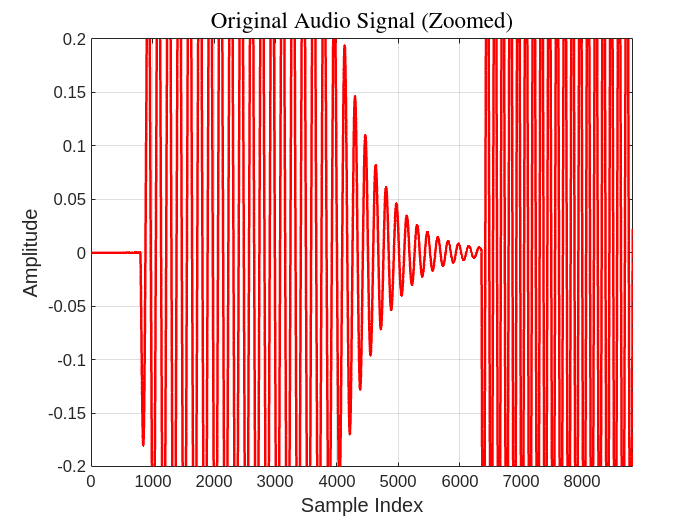


samples_to_plot = round(0.2 * Fs); 

figure;
plot(audio_in(1:samples_to_plot), 'r', 'LineWidth', 1.5);
title('Original Audio Signal (Zoomed)', 'Interpreter', 'latex', 'FontSize', 14);
xlabel('Sample Index', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
xlim([0 samples_to_plot]);
ylim([-0.2 0.2]);
grid on;

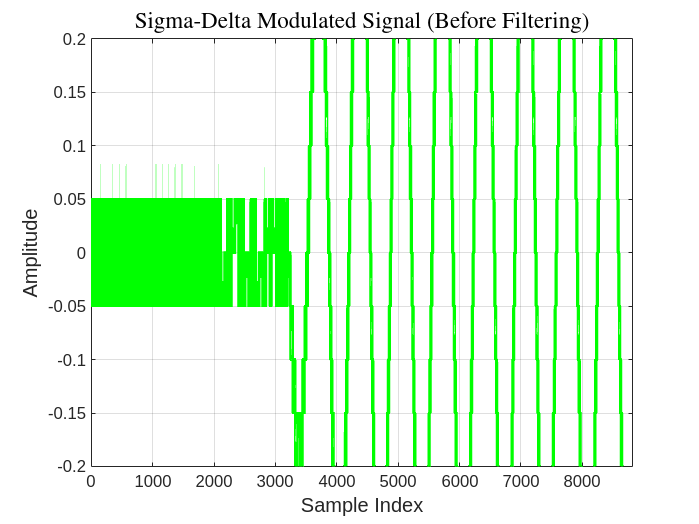


figure;
plot(x_hat(1:samples_to_plot), 'g', 'LineWidth', 1.5);
title('Sigma-Delta Modulated Signal (Before Filtering)', 'Interpreter', 'latex', 'FontSize', 14);
xlabel('Sample Index', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
xlim([0 samples_to_plot]);
ylim([-0.2 0.2]);
grid on;

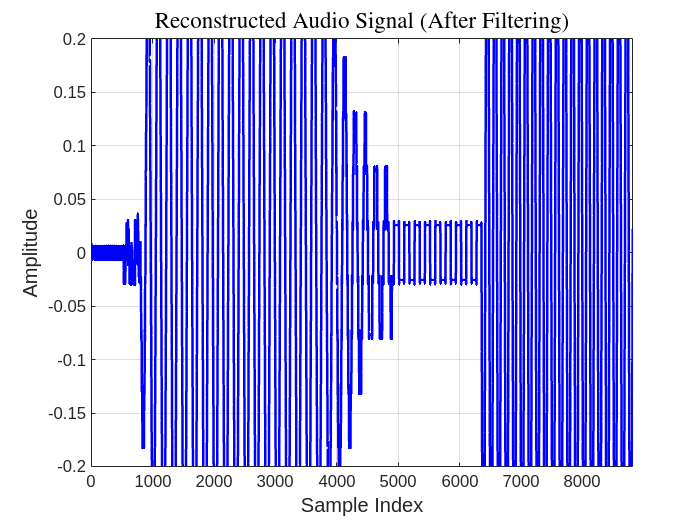

    
figure;
plot(x_reconstructed(1:samples_to_plot), 'b', 'LineWidth', 1.5);
title('Reconstructed Audio Signal (After Filtering)', 'Interpreter', 'latex', 'FontSize', 14);
xlabel('Sample Index', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
xlim([0 samples_to_plot]);
ylim([-0.2 0.2]);
grid on;

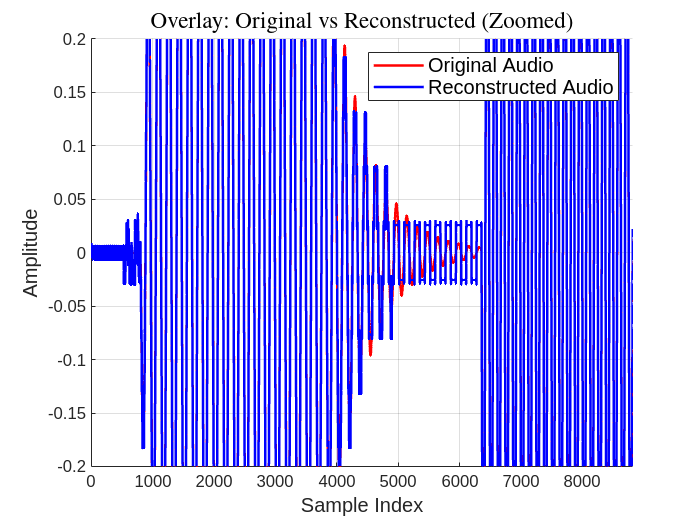


figure;
hold on;
plot(audio_in(1:samples_to_plot), 'r', 'LineWidth', 1.5);
plot(x_reconstructed(1:samples_to_plot), 'b', 'LineWidth', 1.5);
hold off;
title('Overlay: Original vs Reconstructed (Zoomed)', 'Interpreter', 'latex', 'FontSize', 14);
xlabel('Sample Index', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
legend({'Original Audio', 'Reconstructed Audio'}, 'FontSize', 12);
xlim([0 samples_to_plot]);
ylim([-0.2 0.2]);
grid on;